# Embed Audio and Video Using HTML File

Create an HTML file to embed audio and video elements in your app and reference media source files.

First, create an empty HTML UI component in a figure.

fig = uifigure;
fig.Position = [500 500 380 445];

h = uihtml(fig);
h.Position = [10 10 360 420];

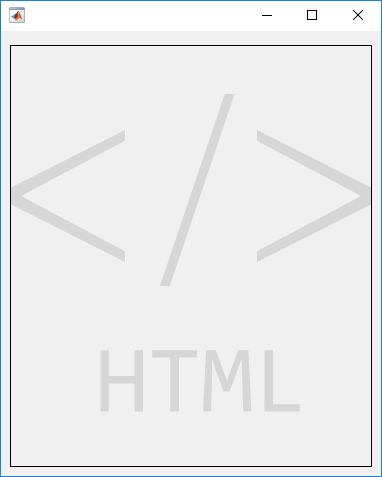

Then, create an HTML file called `audio_videoplayers.html`. In the file, add audio and video elements and specify their file sources relative to the path of the HTML file.  In this example, the media files are in the same directory as the HTML file.

A good practice is to specify multiple file sources for each element because not all contexts support the same file types. For example, MP4 videos are not supported for HTML components in the MATLAB Desktop but are supported in MATLAB Online™. In the video element, specify an OGA file as the first video for the app to try to play. Then, specify an MP4 file as a fallback if the first file is not supported.

Now, embed the HTML file in your app by setting the `HTMLSource` property to the full path to the file.

h.HTMLSource = fullfile(pwd,'audio_videoplayers.html');

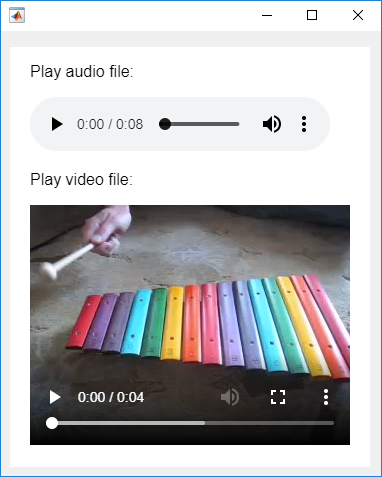

*Copyright 2019 The MathWorks, Inc.*